# Process the intensity data from Idler

Theta = (0,2) degrees.

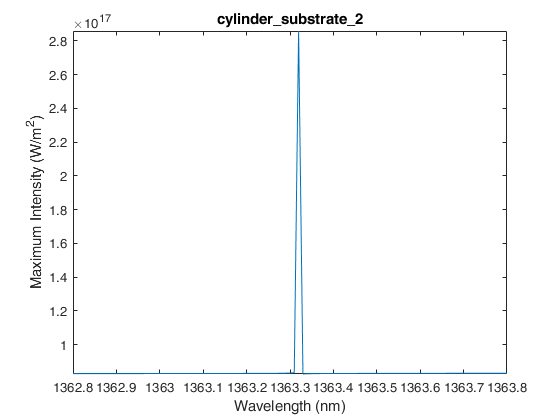

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis'));
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed'));

cylinder_dimer_no_substrate_110_13 = ["cylinder_dimer_no_substrate_110_13_1",...
    "cylinder_dimer_no_substrate_110_13_2","cylinder_dimer_no_substrate_110_13_3",...
    "cylinder_dimer_no_substrate_110_13_4","cylinder_dimer_no_substrate_110_13_5",...
    "cylinder_dimer_no_substrate_110_13_6","cylinder_dimer_no_substrate_110_13_7",...
    "cylinder_dimer_no_substrate_110_13_8","cylinder_dimer_no_substrate_110_13_9",...
    "cylinder_dimer_no_substrate_110_13_11","cylinder_dimer_no_substrate_110_13_12",...
    "cylinder_dimer_no_substrate_110_13_13"];
cylinder_dimer_no_substrate_111_28 = ["cylinder_dimer_no_substrate_111_28_1",...
    "cylinder_dimer_no_substrate_111_28_2","cylinder_dimer_no_substrate_111_28_3",...
    "cylinder_dimer_no_substrate_111_28_4","cylinder_dimer_no_substrate_111_28_5",...
    "cylinder_dimer_no_substrate_111_28_6","cylinder_dimer_no_substrate_111_28_7",...
    "cylinder_dimer_no_substrate_111_28_8","cylinder_dimer_no_substrate_111_28_9",...
    "cylinder_dimer_no_substrate_111_28_11","cylinder_dimer_no_substrate_111_28_12",...
    "cylinder_dimer_no_substrate_111_28_13"];
cylinder_dimer_no_substrate_110 = ["cylinder_dimer_no_substrate_110_2",...
    "cylinder_dimer_no_substrate_110_3","cylinder_dimer_no_substrate_110_4",...
    "cylinder_dimer_no_substrate_110_5","cylinder_dimer_no_substrate_110_6",...
    "cylinder_dimer_no_substrate_110_7","cylinder_dimer_no_substrate_110_8",...
    "cylinder_dimer_no_substrate_110_9","cylinder_dimer_no_substrate_110_10"];
cylinder_dimer_no_substrate_110_2_all = ["cylinder_dimer_no_substrate_110_2",...
    "cylinder_dimer_no_substrate_110_2_1","cylinder_dimer_no_substrate_110_2_2",...
    "cylinder_dimer_no_substrate_110_2_3",...
    "cylinder_dimer_no_substrate_110_2_4","cylinder_dimer_no_substrate_110_2_5"];

cylinder_dimer_substrate_111 = ["cylinder_dimer_substrate_111_1_1",...
    "cylinder_dimer_substrate_111_2_1","cylinder_dimer_substrate_111_3_1"];

cylinder_dimer_no_substrate_111_32_crosspol = ["cylinder_dimer_no_substrate_111_32_7",...
    "cylinder_dimer_no_substrate_111_32_8","cylinder_dimer_no_substrate_111_32_9",...
    "cylinder_dimer_no_substrate_111_32_16","cylinder_dimer_no_substrate_111_32_17",...
    "cylinder_dimer_no_substrate_111_32_18","cylinder_dimer_no_substrate_111_32_13",...
    "cylinder_dimer_no_substrate_111_32_11","cylinder_dimer_no_substrate_111_32_12"];
cylinder_dimer_no_substrate_111_32_copol = ["cylinder_dimer_no_substrate_111_32_19",...
    "cylinder_dimer_no_substrate_111_32_20","cylinder_dimer_no_substrate_111_32_21",...
    "cylinder_dimer_no_substrate_111_32_22","cylinder_dimer_no_substrate_111_32_23",...
    "cylinder_dimer_no_substrate_111_32_24","cylinder_dimer_no_substrate_111_32_25",...
    "cylinder_dimer_no_substrate_111_32_26","cylinder_dimer_no_substrate_111_32_27"];

cylinder_dimer_no_substrate_111_33_crosspol = ["cylinder_dimer_no_substrate_111_33_7",...
    "cylinder_dimer_no_substrate_111_33_8","cylinder_dimer_no_substrate_111_33_9",...
    "cylinder_dimer_no_substrate_111_33_16","cylinder_dimer_no_substrate_111_33_17",...
    "cylinder_dimer_no_substrate_111_33_18","cylinder_dimer_no_substrate_111_33_13",...
    "cylinder_dimer_no_substrate_111_33_11","cylinder_dimer_no_substrate_111_33_12"];
cylinder_dimer_no_substrate_111_33_copol = ["cylinder_dimer_no_substrate_111_33_19",...
    "cylinder_dimer_no_substrate_111_33_20","cylinder_dimer_no_substrate_111_33_21",...
    "cylinder_dimer_no_substrate_111_33_22","cylinder_dimer_no_substrate_111_33_23",...
    "cylinder_dimer_no_substrate_111_33_24","cylinder_dimer_no_substrate_111_33_25",...
    "cylinder_dimer_no_substrate_111_33_26","cylinder_dimer_no_substrate_111_33_27"];

fig = figure;
    
%for job = cylinder_dimer_substrate_111
intensity_enhancement_crosspol = [];
for job = "cylinder_substrate_2"
%for job = ["spheres_3_2"]
    eval(job);    
    if ~isempty(options.base_data_dir_final)
        load([options.output_dir_final 'derived_values.mat']);
    else
        load([options.output_dir 'derived_values.mat']);
    end
    extra_options = matthew_extra_options(options);

    wlengths = 299792458./derived_values.signal.freq;
    %intensity_enhancement_crosspol = [intensity_enhancement_crosspol,...
    %    max((derived_values.signal.max_Is))/min((derived_values.signal.max_Is))];
    intensity_enhancement_crosspol = [intensity_enhancement_crosspol,...
        max(log10(derived_values.signal.max_Is))/min(log10(derived_values.signal.max_Is))];
    %fig = figure;
    %yyaxis left;
    plot(wlengths, (derived_values.signal.max_Is)); 
    
    %plot(derived_values.signal.max_Is); 
    hold on
    ylabel('Maximum Intensity (W/m^2)');
    %{
    yyaxis right;
    plot(wlengths, log10(derived_values.signal.int_Is)); 
    %plot(log10(derived_values.signal.int_Is));
    leg_scat3 = legend({'Max(I) in resonator','\int_{resonator} I dV'});
    leg_scat3.Location = 'northeast';
    %}
    xlabel('Wavelength (nm)');
    %ylabel('log_{10}(\int Intensity dV)');
    axis tight;
    title(job, 'Interpreter', 'none');
    saveas(fig, strcat("C:\Users\Matthew\Downloads\",job), 'png');
end